line_list_1 = importdata('LINE_LIST_1.DAT');
line_list_2 = importdata('LINE_LIST_2.DAT');
point_list_1 = importdata('POINT_LIST_1.DAT');
point_list_2 = importdata('POINT_LIST_2.DAT');

% create edges
line_list = line_list_2;
point_list= point_list_2;
% -------------------------------------
line = [line_list(1,2)];
for n = 2: length(line_list(:,1))
    index = find(line_list(:,2) == line(end));
    line(n) = line_list(index,3);
end 

line = line';

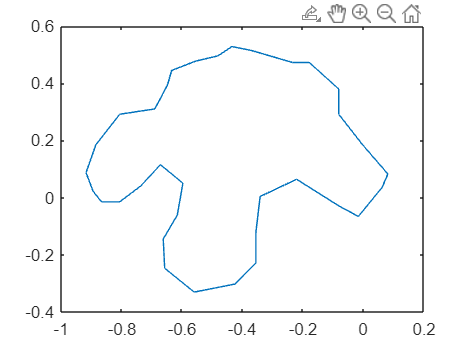

wrapped_line = [line(end);line;line(1)];
XY = point_list(line, 2:3);
wrappedXY = point_list(wrapped_line, 2:3);
figure(1), clf
plot(wrappedXY(:,1), wrappedXY(:,2))

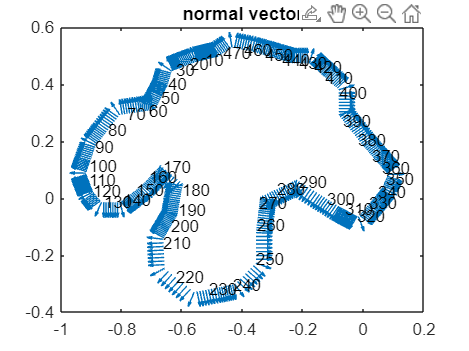


deltaXY = wrappedXY(3:end,:) - wrappedXY(1:end-2,:);
n_v = deltaXY ./ sqrt(deltaXY(:,1).^2 + deltaXY(:,2).^2) ;
n_v = [n_v(:,2), -n_v(:,1)];
quiver(XY(:,1), XY(:,2), n_v(:,1), n_v(:,2))
title('normal vector')
% hold on
for n = 1:length(XY(:,1))
    if mod(n, 10)==0
        text(XY(n,1),XY(n,2), string(n))
    end
end

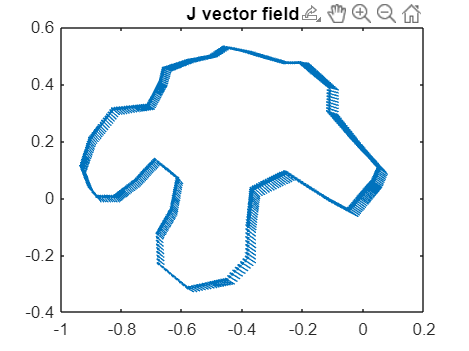

quiver(XY(:,1), XY(:,2), J_field(:,1), J_field(:,2))
title('J vector field')

% The direction of the vector field were plotted at each points and it
% points from the bottom right to the top left
J_field = point_list(line, 4:5);
J_field_projection_for_each_point = dot(J_field, n_v, 2);
J_field_projection = [J_field_projection_for_each_point;
    J_field_projection_for_each_point(1)];

J_field_projection =     8.4715
    5.6815
    5.7753
    5.8695
    5.9653
    6.0627
    6.1621
    6.2640
    6.3334
    6.4044


% calculate lengeth between each 2 points / 2
new_wrapped_line = wrapped_line(2:end);

new_wrapped_line =      1
   237
   119
   355
    60
   296
   178
   414
    59
   295


new_wrappedXY = point_list(new_wrapped_line, 2:3);

new_wrappedXY =    -0.4810    0.4957
   -0.4856    0.4945
   -0.4903    0.4933
   -0.4949    0.4922
   -0.4996    0.4910
   -0.5042    0.4899
   -0.5088    0.4887
   -0.5135    0.4875
   -0.5181    0.4864
   -0.5228    0.4852


differenceXY = new_wrappedXY(2:end,:) - new_wrappedXY(1:end-1,:);
length_segments = sqrt(differenceXY(:,1).^2 + differenceXY(:,2).^2);

length_segments =     0.0048
    0.0048
    0.0048
    0.0048
    0.0048
    0.0048
    0.0048
    0.0048
    0.0048
    0.0048



line_integration = sum(J_field_projection(1:end-1).*(length_segments/2) ... 
    + J_field_projection(2:end).*(length_segments/2));

fprintf('Line integration for pointlist: %f', line_integration)

Line integration for pointlist: -10.327510

IF we phave **phi1** in the integration

line_list_1 = importdata('LINE_LIST_1.DAT');
line_list_2 = importdata('LINE_LIST_2.DAT');
point_list_1 = importdata('POINT_LIST_1.DAT');
point_list_2 = importdata('POINT_LIST_2.DAT');

% create edges
line_list = line_list_1;
point_list= point_list_1;
% -------------------------------------
line = [line_list(1,2)];
for n = 2: length(line_list(:,1))
    index = find(line_list(:,2) == line(end));
    line(n) = line_list(index,3);
end 
line = line';
wrapped_line = [line(end);line;line(1)];
XY = point_list(line, 2:3);
wrappedXY = point_list(wrapped_line, 2:3);
deltaXY = wrappedXY(3:end,:) - wrappedXY(1:end-2,:);
n_v = deltaXY ./ sqrt(deltaXY(:,1).^2 + deltaXY(:,2).^2) ;
n_v = [n_v(:,2), -n_v(:,1)];

J_field = point_list(line, 4:5);
J_field_projection_for_each_point = dot(J_field, n_v, 2);
J_field_projection = [J_field_projection_for_each_point;
    J_field_projection_for_each_point(1)];
% calculate lengeth between each 2 points / 2
new_wrapped_line = wrapped_line(2:end);
new_wrappedXY = point_list(new_wrapped_line, 2:3);
differenceXY = new_wrappedXY(2:end,:) - new_wrappedXY(1:end-1,:);
length_segments = sqrt(differenceXY(:,1).^2 + differenceXY(:,2).^2);

line_integration = sum(J_field_projection(1:end-1).*(length_segments/3) ... 
    + J_field_projection(2:end).*(length_segments/6));

fprintf('Line integration with phi1 for pointlist: %f', line_integration)

Line integration with phi1 for pointlist: -0.016334

For line integration with **phi2**

line_list_1 = importdata('LINE_LIST_1.DAT');
line_list_2 = importdata('LINE_LIST_2.DAT');
point_list_1 = importdata('POINT_LIST_1.DAT');
point_list_2 = importdata('POINT_LIST_2.DAT');

% create edges
line_list = line_list_2;
point_list= point_list_2;
% -------------------------------------
line = [line_list(1,2)];
for n = 2: length(line_list(:,1))
    index = find(line_list(:,2) == line(end));
    line(n) = line_list(index,3);
end 
line = line';
wrapped_line = [line(end);line;line(1)];
XY = point_list(line, 2:3);
wrappedXY = point_list(wrapped_line, 2:3);
deltaXY = wrappedXY(3:end,:) - wrappedXY(1:end-2,:);
n_v = deltaXY ./ sqrt(deltaXY(:,1).^2 + deltaXY(:,2).^2) ;
n_v = [n_v(:,2), -n_v(:,1)];

J_field = point_list(line, 4:5);
J_field_projection_for_each_point = dot(J_field, n_v, 2);
J_field_projection = [J_field_projection_for_each_point;
    J_field_projection_for_each_point(1)];
% calculate lengeth between each 2 points / 2
new_wrapped_line = wrapped_line(2:end);
new_wrappedXY = point_list(new_wrapped_line, 2:3);
differenceXY = new_wrappedXY(2:end,:) - new_wrappedXY(1:end-1,:);
length_segments = sqrt(differenceXY(:,1).^2 + differenceXY(:,2).^2);

line_integration = sum(J_field_projection(1:end-1).*(length_segments/1) ... 
    + J_field_projection(2:end).*(length_segments/3));

fprintf('Line integration with phi2 for pointlist: %f', line_integration)

Line integration with phi2 for pointlist: -13.773760